syms l_1 l_2 l_3 l_4 l_5
M = [1 0 0 0;
     0 1 0 0;
     0 0 1 l_1+l_2+l_3+l_4+l_5;
     0 0 0 1;
    ]

$$M = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{1}+l_{2}+l_{3}+l_{4}+l_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

w1 = [0;0;1];
q1 = [0;0;l_1];
S1 = [w1;cross(-w1,q1)]

$$S1 = \left(\begin{array}{c} 0\\ 0\\ 1\\ 0\\ 0\\ 0 \end{array}\right)$$

w2 = [1;0;0];
q2 = [0;0;l_1+l_2];
S2 = [w2;cross(-w2,q2)]

$$S2 = \left(\begin{array}{c} 1\\ 0\\ 0\\ 0\\ l_{1}+l_{2}\\ 0 \end{array}\right)$$

w3 = [1;0;0];
q3 = [0;0;l_1+l_2+l_3];
S3 = [w3;cross(-w3,q3)]

$$S3 = \left(\begin{array}{c} 1\\ 0\\ 0\\ 0\\ l_{1}+l_{2}+l_{3}\\ 0 \end{array}\right)$$

w4 = [1;0;0];
q4 = [0;0;l_1+l_2+l_3+l_4];
S4 = [w4;cross(-w4,q4)];
syms theta_1 theta_2 theta_3 theta_4
T = simplify(exp(S1,theta_1)*exp(S2,theta_2)*exp(S3,theta_3)*exp(S4,theta_4)*M)

$$T = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sigma_{1}\,\sin\left(\theta_{1}\right) & \sigma_{3}\,\sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{2}\\ \sin\left(\theta_{1}\right) & \sigma_{1}\,\cos\left(\theta_{1}\right) & -\sigma_{3}\,\cos\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\sigma_{2}\\ 0 & \sigma_{3} & \sigma_{1} & l_{1}+l_{2}+l_{4}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{3}\,\cos\left(\theta_{2}\right)+l_{5}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{2}=l_{4}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{3}\,\sin\left(\theta_{2}\right)+l_{5}\,\sigma_{3}\\ \sigma_{3}=\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

position = T(1:3,4)

$$position = \begin{array}{l} \left(\begin{array}{c} \sin\left(\theta_{1}\right)\,\sigma_{1}\\ -\cos\left(\theta_{1}\right)\,\sigma_{1}\\ l_{1}+l_{2}+l_{4}\,\cos\left(\theta_{2}+\theta_{3}\right)+l_{3}\,\cos\left(\theta_{2}\right)+l_{5}\,\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{4}\,\sin\left(\theta_{2}+\theta_{3}\right)+l_{3}\,\sin\left(\theta_{2}\right)+l_{5}\,\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

rotation = T(1:3,1:3)

$$rotation = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & -\cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\sin\left(\theta_{1}\right) & \sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\sin\left(\theta_{1}\right)\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right)\,\cos\left(\theta_{1}\right)\\ 0 & \sin\left(\theta_{2}+\theta_{3}+\theta_{4}\right) & \cos\left(\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}\right)$$

theta_1 = deg2rad(0);
theta_2 = deg2rad(0);
theta_3 = deg2rad(0);
theta_4 = deg2rad(0);

[x,y,z,R] = pincherFK(theta_1, theta_2, theta_3, theta_4);
disp(x); 

     0



disp(y); 

     0



disp(z); 

    0.4520



disp(R);

     1     0     0
     0     1     0
     0     0     1



theta_1 = deg2rad(0);
theta_2 = deg2rad(0);
theta_3 = deg2rad(0);
theta_4 = deg2rad(-90);

[x,y,z,R] = pincherFK(theta_1, theta_2, theta_3, theta_4);
disp(x); 

     0



disp(y); 

    0.0950



disp(z); 

    0.3570



disp(R);

    1.0000         0         0
         0    0.0000    1.0000
         0   -1.0000    0.0000



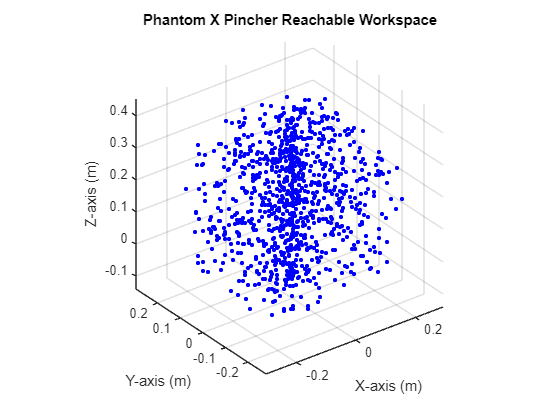

% Number of random configurations to sample
numSamples = 1000;

% Joint limits (all -150° to 150°)
theta_min = deg2rad(-150);
theta_max = deg2rad(150);

% Generate random joint configurations within limits
theta_1 = theta_min + (theta_max - theta_min) * rand(numSamples, 1);
theta_2 = theta_min + (theta_max - theta_min) * rand(numSamples, 1);
theta_3 = theta_min + (theta_max - theta_min) * rand(numSamples, 1);
theta_4 = theta_min + (theta_max - theta_min) * rand(numSamples, 1);

% Initialize arrays for storing end-effector positions
X = zeros(numSamples, 1);
Y = zeros(numSamples, 1);
Z = zeros(numSamples, 1);

% Compute end-effector positions for each sampled configuration
for i = 1:numSamples
    [X(i), Y(i), Z(i), ~] = pincherFK(theta_1(i), theta_2(i), theta_3(i), theta_4(i));
end

% 3D Scatter Plot - Isometric View
figure;
scatter3(X, Y, Z, 10, 'b', 'filled');
xlabel('X-axis (m)');
ylabel('Y-axis (m)');
zlabel('Z-axis (m)');
title('Phantom X Pincher Reachable Workspace');
grid on;
axis equal;
view(3); % Isometric View

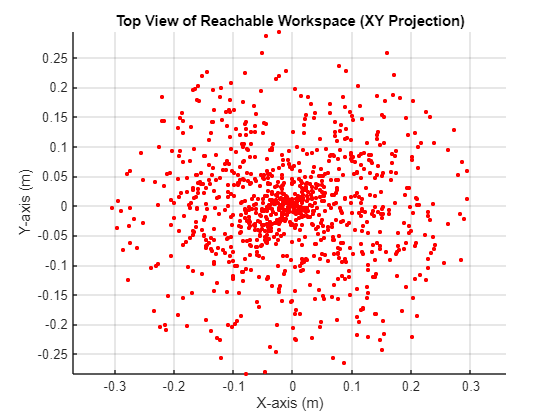


% 2D Projection - Top-down View (XY Plane)
figure;
scatter(X, Y, 10, 'r', 'filled');
xlabel('X-axis (m)');
ylabel('Y-axis (m)');
title('Top View of Reachable Workspace (XY Projection)');
grid on;
axis equal;


% Maximum Horizontal Reach (Farthest point from origin in XY plane)
max_horizontal_reach = max(sqrt(X.^2 + Y.^2));
disp(['Maximum Horizontal Reach: ', num2str(max_horizontal_reach), ' meters']);

Maximum Horizontal Reach: 0.305 meters


arm.delete()

arm = Arbotix('port', 'COM4', 'nservos', 5);

serPort COM4is in use.   Closing it.


i = 4

arm.setpos(1,0)
arm.setpos(2,0)
arm.setpos(3,pi/2)
arm.setpos(4,0)
[x,y,z, R] = findPincher(arm)

x = -0.0021

y = 0.2055

z = 0.2316

R =     0.9999    0.0010   -0.0102
    0.0102   -0.1011    0.9948
         0   -0.9949   -0.1011


[x,y,z, R] = findPincher(arm)

function [x, y, z, R] = pincherFK(theta_1, theta_2, theta_3, theta_4)
    % Computes the forward kinematics.
    % Inputs:
    %   theta_1 - Joint 1 angle (Base rotation) in radians
    %   theta_2 - Joint 2 angle (Shoulder rotation) in radians
    %   theta_3 - Joint 3 angle (Elbow rotation) in radians
    %   theta_4 - Joint 4 angle (Wrist rotation) in radians
    %
    % Outputs:
    %   x - X-coordinate of the end-effector in meters
    %   y - Y-coordinate of the end-effector in meters
    %   z - Z-coordinate of the end-effector in meters
    %   R - 3x3 Rotation matrix representing the end-effector orientation

    % Link lengths (converted from cm to meters)
    l_1 = 10 / 100;   % Length of Link 1
    l_2 = 4.5 / 100;  % Length of Link 2
    l_3 = 10.7 / 100; % Length of Link 3
    l_4 = 10.5 / 100; % Length of Link 4
    l_5 = 9.5 / 100;  % Length of Link 5 (End-effector offset)

    % Home position transformation matrix (end-effector frame at zero position)
    M = [1 0 0 0;
         0 1 0 0;
         0 0 1 l_1 + l_2 + l_3 + l_4 + l_5;
         0 0 0 1];

    % Define screw axes in the space frame
    w1 = [0; 0; 1];  % Rotation around Z-axis (Base)
    q1 = [0; 0; l_1];
    S1 = [w1; cross(-w1, q1)];

    w2 = [1; 0; 0];  % Rotation around X-axis (Shoulder)
    q2 = [0; 0; l_1 + l_2];
    S2 = [w2; cross(-w2, q2)];

    w3 = [1; 0; 0];  % Rotation around X-axis (Elbow)
    q3 = [0; 0; l_1 + l_2 + l_3];
    S3 = [w3; cross(-w3, q3)];

    w4 = [1; 0; 0];  % Rotation around X-axis (Wrist)
    q4 = [0; 0; l_1 + l_2 + l_3 + l_4];
    S4 = [w4; cross(-w4, q4)];

    % Compute the transformation matrix using product of exponentials
    T = exp(S1, theta_1) * exp(S2, theta_2) * exp(S3, theta_3) * exp(S4, theta_4) * M;

    % Extract end-effector position
    x = T(1, 4);
    y = T(2, 4);
    z = T(3, 4);

    % Extract rotation matrix
    R = T(1:3, 1:3);
end

function [x,y,z,R] = findPincher(arm)
    % Send arm as input
    angles = arm.getpos(); % Get angles of all joints
    [x,y,z,R] = pincherFK(-angles(1),-angles(2),-angles(3),-angles(4));
    % Call previously made pincherFK function to get the x, y, z
    % coordinates and the rotation matrix. The angles are input as negative
    % because of the way we assigned our screw axes in the forward mapping.
end
function vs = skew(v)
    vs = [0 -v(3) v(2);
          v(3) 0 -v(1);
         -v(2) v(1) 0];
end


function T = exp(S, theta)
    w_skew = skew(S(1:3));
    exp_w = eye(3) + w_skew*sin(theta) + w_skew^2*(1-cos(theta));
    G = eye(3)*theta + (1-cos(theta))*w_skew+(theta-sin(theta))*w_skew^2;
    T = [exp_w, G*S(4:6);
         zeros(1,3), 1];
end